# Powertrain Results

### Visualize results of batteryUKF  from the phm_aug5_powertrain model

time     = out.tout;
voltage  = out.v_batt.Data;
noisy_v  = out.noisy_v.Data;
v_hat    = out.v_batt_hat.Data;
sochat   = out.soc_hat.Data;
socbound = out.soc_bound.Data;
soc      = out.soc.Data;


fprintf('RMS SOC estimation error = %g%%\n',sqrt(mean((100*(soc-sochat)).^2)));

RMS SOC estimation error = 1.61496%


ind = find(abs(soc-sochat)>socbound);
fprintf('Percent of time error outside bounds = %g%%\n',length(ind)/length(soc)*100);

Percent of time error outside bounds = 0%


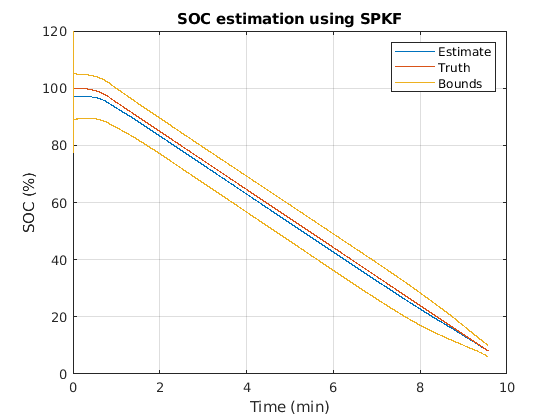

f1 = figure(1);clf;
plot(time/60,100*sochat,time/60,100*soc); hold on
plot([time/60; NaN; time/60],[100*(sochat+socbound); NaN; 100*(sochat-socbound)]);
title('SOC estimation using SPKF'); grid on
xlabel('Time (min)'); ylabel('SOC (%)'); legend('Estimate','Truth','Bounds');
hold off;

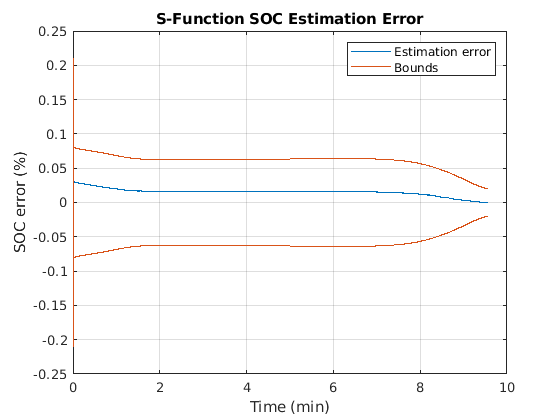


f2 = figure(2); clf;
plot(time/60,(soc-sochat)); hold on
plot([time/60; NaN; time/60],[socbound; NaN; -socbound]);
title('S-Function SOC Estimation Error');
xlabel('Time (min)'); ylabel('SOC error (%)'); 
legend('Estimation error','Bounds'); 
grid on;
hold off;

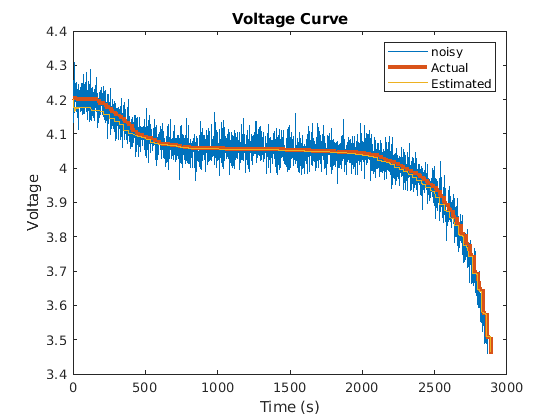

f3 = figure(3); clf;
plot(noisy_v); 
hold on;
plot(voltage, 'Linewidth',3);
plot(v_hat);
legend('noisy', 'Actual', 'Estimated');
hold off;
title("Voltage Curve");
ylabel("Voltage");
xlabel("Time (s)");

### Motor UKF results